# Example for using the `line_intersection` function.

Copyright © 2021 Tamas Kis

## Example #1: Simple example.

*Find the intersection of the following two lines:*


$$y=5x+2$$



$$y-4=7\left(x-10\right)$$


Define the parameters for line 1 (slope-intercept form).

m1 = 5;
b1 = 2;

Define the parameters for line 2 (point-slope form).

x2 = 10;
y2 = 4;
m2 = 7;

Find the intersection point using `line_intersection`.

[x_int,y_int] = line_intersection([m1,b1],[x2,y2,m2])

x_int = 34

y_int = 172

Define the lines for plotting.

x = 0:0.1:50;
line1 = m1*x+b1;
line2 = y2+m2*(x-x2);

Verify the result graphically.

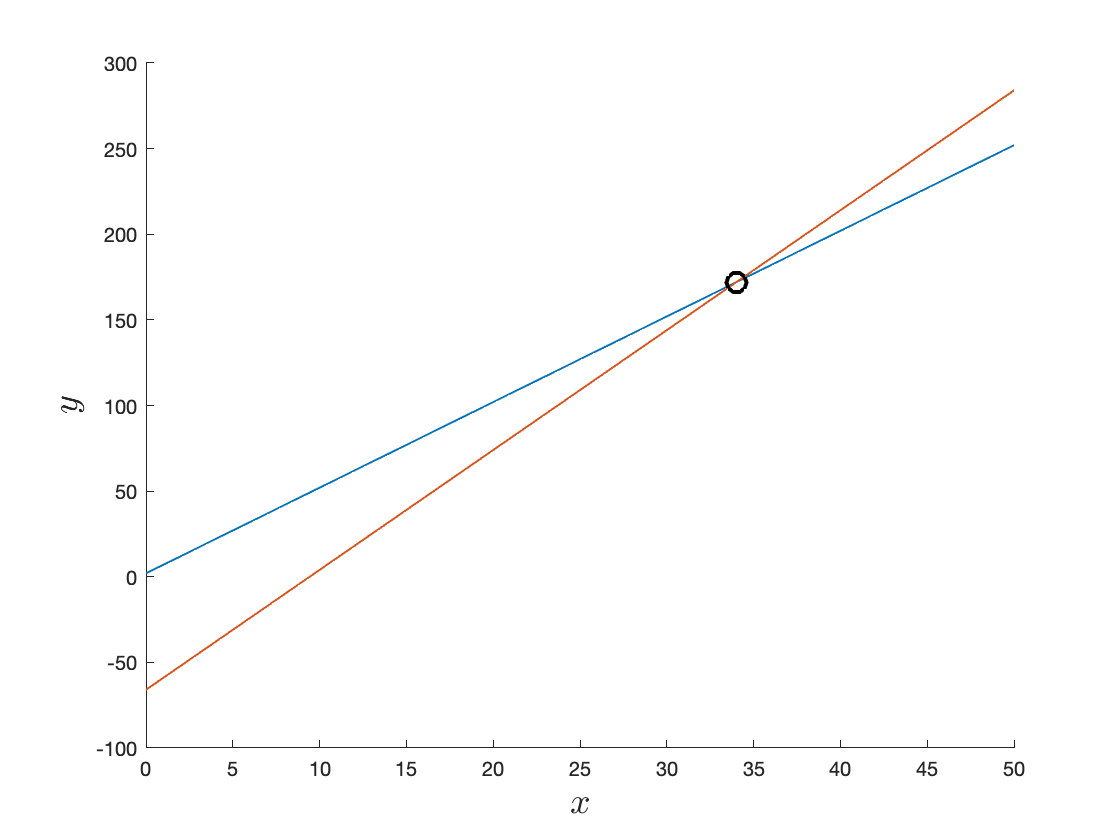

figure;
hold on;
plot(x,line1,'linewidth',1);
plot(x,line2,'linewidth',1);
plot(x_int,y_int,'o','color','k','linewidth',2,'markersize',10);
hold off;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$y$','interpreter','latex','fontsize',18);

## Example #2: Parallel lines.

*Find (or attempt to find) the intersection of the following two lines:*


$$y=5x+2$$



$$y=5x+3$$


Immediately, we know these two lines are parallel and not collinear. Verifying this with `line_intersection`,

[x_int,y_int] = line_intersection([5,2],[5,3])

x_int = Inf

y_int = Inf

## Example #3: Collinear lines.

*Line 1 contains the points *$\left(1,1\right)$* and *$\left(2,2\right)$*, while line 2 contains the points *$\left(3,3\right)$* and *$\left(4,4\right)$*. Find the intersection of the two lines.*

By inspection, we know the two lines are collinear. Verifying using `line_intersection`,

% points defining line 1
x1 = 1; y1 = 1;
x2 = 2; y2 = 2;

% points defining line 2
x3 = 3; y3 = 3;
x4 = 4; y4 = 4;

% intersection of the two lines
[x_int,y_int] = line_intersection([x1,y1,x2,y2],[x3,y3,x4,y4])

x_int = NaN

y_int = NaN

## Example #4: One vertical line.

*Find the intersection of the following two lines:*


$$y=x+1$$



$$x=1$$


Defining the first line,

m1 = 1;
b1 = 1;

Defining the second line,

x2 = 1;

Finding the intersection,

[x_int,y_int] = line_intersection([m1,b1],x2)

x_int = 1

y_int = 2

## Example #5: Parallel vertical lines.

*Find (or attempt to find) the intersection of the following two lines:*


$$x=1$$



$$x=2$$


By inspection, the two lines are vertical and parallel. Confirming this using the `line_intersection` function,

[x_int,y_int] = line_intersection(1,2)

x_int = Inf

y_int = Inf

## Example #6: Collinear vertical lines.

*Line 1 contains the points *$\left(0,0\right)$* and *$\left(0,1\right)$*, while line 2 is the vertical line *$x=0$*. Find (or attempt to find) the intersection of the two lines.*

By inspection, lines 1 and 2 are the same vertical line. Confirming this using `line_intersection`,

[x_int,y_int] = line_intersection([0,0,0,1],0)

x_int = 0

y_int = NaN